# Example 6.24: GP Model for Gibbs Reactor

Note: this script reproduces Example 6.24 (Section 6.6) of **Statistics for Chemical Engineers**: a Gaussian process (kriging) model of the Gibbs reactor, compared with linear regression. Victor Z UW-Madison, 2020 Gaussian process (kriging) prediction for gibbs data [https://www.mathworks.com/help/stats/fitrgp.html](https://www.mathworks.com/help/stats/fitrgp.html) [https://www.mathworks.com/help/stats/compactregressiongp.predict.html](https://www.mathworks.com/help/stats/compactregressiongp.predict.html)

clc; clear all; close all hidden

## Data

create data set

load ('./Data/gibbs_hightemp_class.dat')
datahigh=gibbs_hightemp_class;
load ('./Data/gibbs_lowtemp_class.dat')
datalow=gibbs_lowtemp_class;
data=[datahigh;datalow];
n=length(data);

rng(0);
inputs=data(:,1:2)'+rand(2,n)*0.1;  % temperature and pressure
targets=data(:,3)'+rand(1,n)*0.1;   % yield

## GP model

define kriging model

gprMdl = fitrgp(inputs',targets','KernelFunction','squaredexponential')

gprMdl =   RegressionGP
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 500
           KernelFunction: 'SquaredExponential'
        KernelInformation: [1×1 struct]
            BasisFunction: 'Constant'
                     Beta: 0.3441
                    Sigma: 0.0284
        PredictorLocation: []
           PredictorScale: []
                    Alpha: [500×1 double]
         ActiveSetVectors: [500×2 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 500
                FitMethod: 'Exact'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [500×1 logical]
            LogLikelihood: 1.0511e+03
         ActiveSetHistory: []
           BCDInformation: []

  Properties, Methods


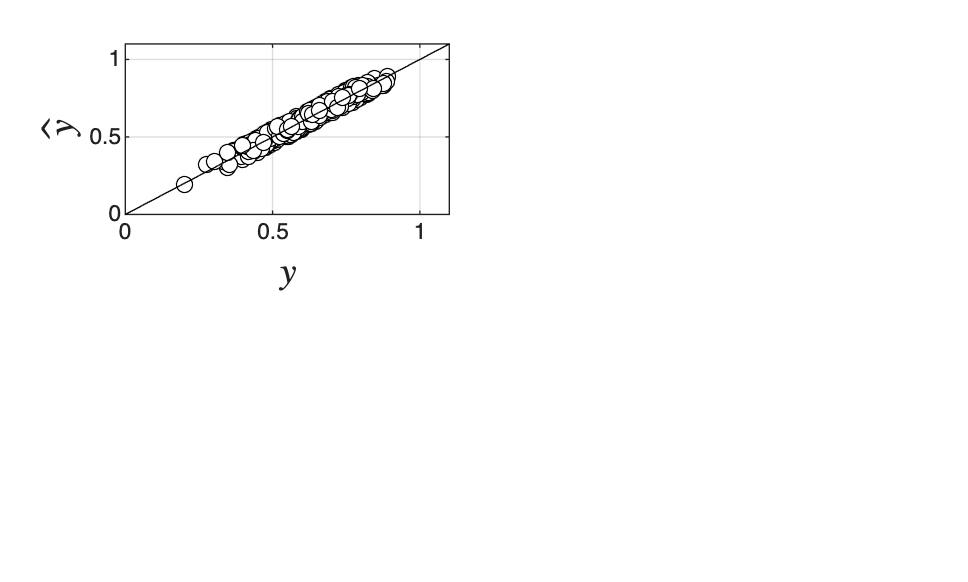

[outputsgpr,outputsd,outputsci] = predict(gprMdl,inputs');
eps=targets'-outputsgpr;

% plot fit
figure(1)
subplot(2,2,1)
xx=linspace(0,1.1);
plot(targets,outputsgpr,'blacko','MarkerFaceColor','w')
grid on
hold on
plot(xx,xx,'black-')
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0,1.1,0,1.1])

## Linear regression and comparison

define linear regression model

mdl = fitlm(inputs',targets')

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate         SE         tStat       pValue   
                   __________    __________    _______    ___________
    (Intercept)        4.5159      0.056692     79.657    3.6905e-285
    x1             -0.0072452    9.3738e-05    -77.291    3.8865e-279
    x2              0.0030381    5.5627e-05     54.616     3.555e-212

Number of observations: 500, Error degrees of freedom: 497
Root Mean Squared Error: 0.0314
R-squared: 0.947,  Adjusted R-Squared: 0.947
F-statistic vs. constant model: 4.48e+03, p-value = 1.29e-318

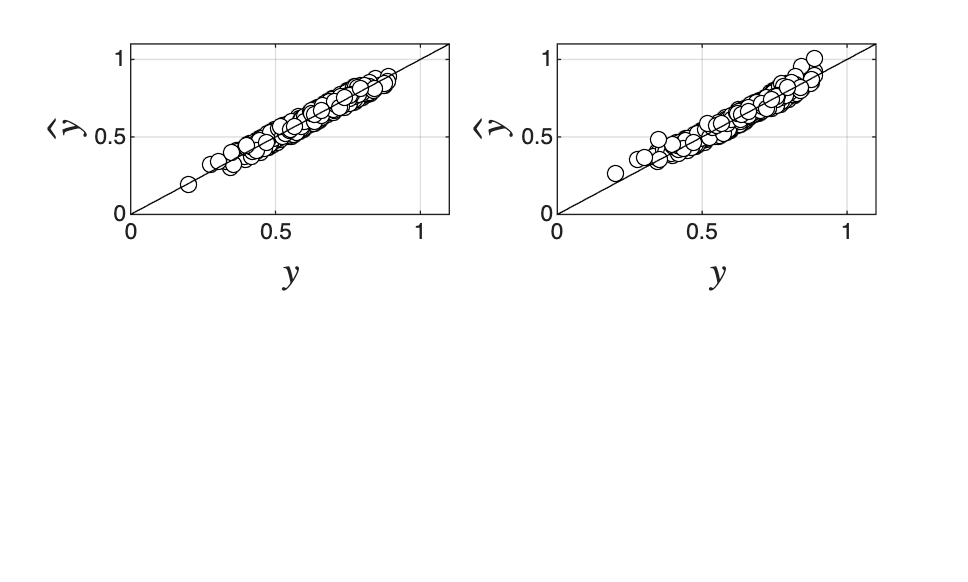

outputsLR = predict(mdl,inputs');
eps2=targets'-outputsLR;

figure(1)
subplot(2,2,2)
plot(targets,outputsLR,'blacko','MarkerFaceColor','w')
hold on
grid on
plot(xx,xx,'black-')
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0,1.1,0,1.1])
print -depsc ch6_fit_gibbs_kriging_linear.eps

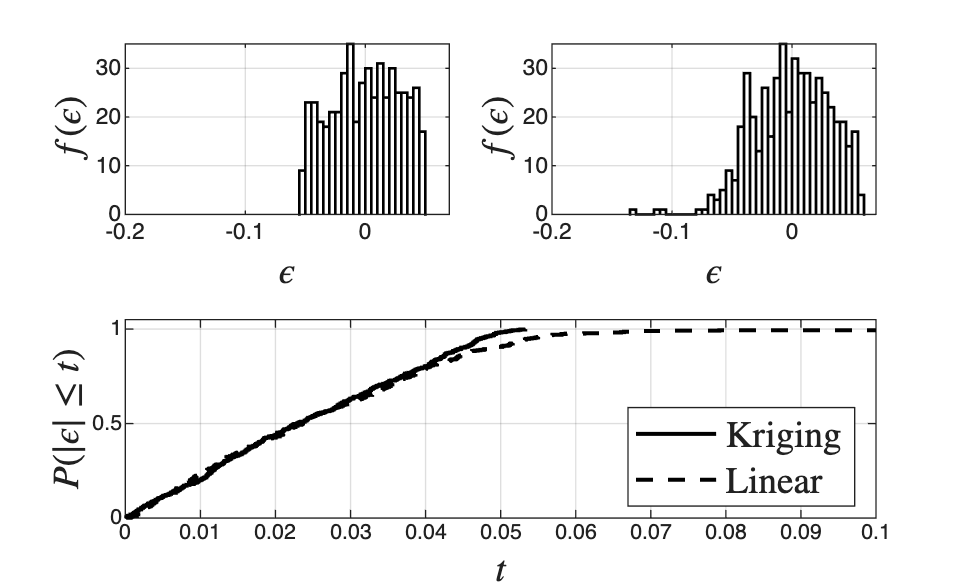


% compare benchmark using cdfs and pdfs of residuals
figure(3)
subplot(2,2,1)
histogram(eps,'BinWidth',0.005,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
grid on
xlabel('$\epsilon$','Interpreter','latex','FontSize',14)
ylabel('$f(\epsilon)$','Interpreter','latex','FontSize',14)
axis([-0.2 0.07 0 35])
subplot(2,2,2)
histogram(eps2,'BinWidth',0.005,'Normalization','count','EdgeColor','black','FaceColor','none','LineWidth',1)
grid on
xlabel('$\epsilon$','Interpreter','latex','FontSize',14)
ylabel('$f(\epsilon)$','Interpreter','latex','FontSize',14)
axis([-0.2 0.07 0 35])

[F1,X1]=ecdf(abs(eps));
[F2,X2]=ecdf(abs(eps2));
subplot(2,2,[3 4])
stairs(X1,F1,'black-','LineWidth',1.5)
hold on
stairs(X2,F2,'black--','LineWidth',1.5)
grid on
axis([0,0.1,0,1.05])
xlabel('$t$','Interpreter','latex','FontSize',14)
ylabel('$P(|\epsilon|\leq t)$','Interpreter','latex','FontSize',14)
legend('$\textrm{Kriging}$','$\textrm{Linear}$','Location','southeast','Interpreter','latex','FontSize',14)
print -depsc ch6_benchmark_gibbs_kriging_linear_pdf_cdf.eps

## Uncertainty bands

plot confidence intervals for gpr

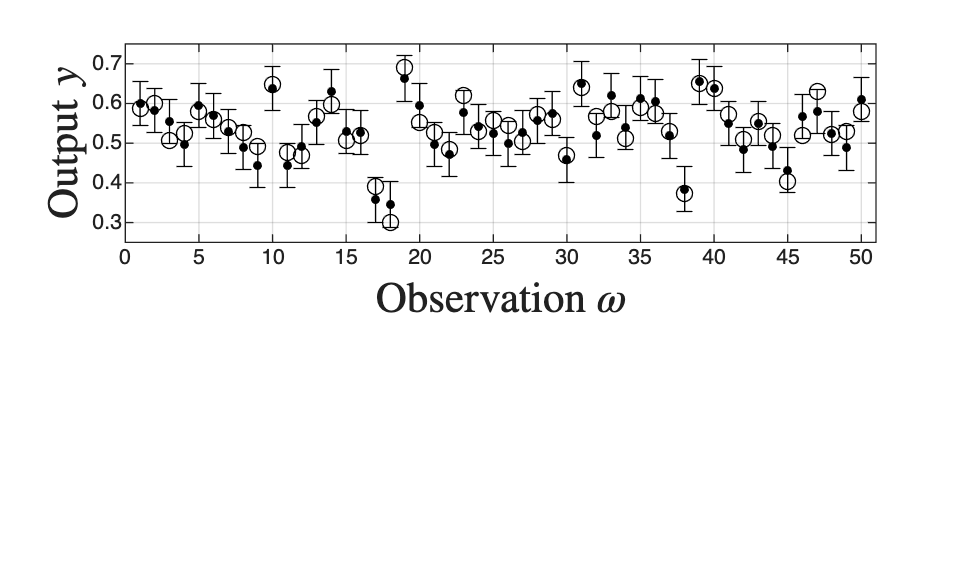

c1=outputsci(:,1);
c2=outputsci(:,2);
E=(c2-c1)/2;

figure(4)
subplot(2,2,[1:2])
errorbar(1:50,targets(1:50),E(1:50),'black.','MarkerSize',10);
hold on;
scatter(1:50,outputsgpr(1:50),'blacko','MarkerFaceColor','None')
%stairs(c1(1:50),'Color',[0.5 0.5 0.5]);
%stairs(c2(1:50),'Color',[0.5 0.5 0.5]);
axis([0 51 0.25 0.75])
xlabel('Observation $\omega$','Interpreter','latex','FontSize',16)
ylabel('Output $y$','Interpreter','latex','FontSize',16)
grid on
print -depsc ch6_conf_gibbs.eps

## Note

As in the book, the observed values always lie within the predicted confidence intervals: the GP characterizes its uncertainty consistently.